binned_pdf_example

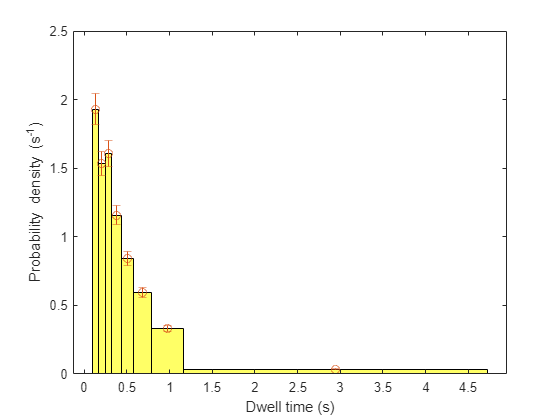

load("biexp_test_dat.mat")
[bin_centers, y, bins, se] = binned_pdf(ts, 8);
histogram('BinEdges',bins, 'BinCounts',y,'FaceColor','y') % plots bars
hold on
errorbar(bin_centers, y, se,'o'); % plots points and error bars
xlabel('Dwell time (s)')
ylabel('Probability density (s^{-1})')
hold off